is_Mac = 0;

Windtunnell Session April post analysis

- Transition 1/2

- Forward Flight -

- Hover Flight and scheduling of effectiveness with skew

- Kill bug -

- Pitch behaviour (actuator dynamics)

- WLS bug fix -

- Scaling of virtual inputs -

- Tail pitch up

Let's analyse every topic

### WLS bug fix

The old outerloop wls code when checking for saturation was evaluating:

The additional 1.0 offset are used to avoid the case scenario in which the absolute difference between the calculated optimal u and the saturation limit falls under 0.00005 which probably has to do with how floating point numbers are defined. Testing of the code has lead to the output of Nan in the case of the removal of this 1.0 offset when close to saturation. 

In the innerloop pprz commands are being evaluated which range from 0 to 9600. In this scale, a 1.0 offset is negligible. On the other hand, in the outerloop where we use Thrust comands and angles, 1.0 can result to be a large percentage of the avialable range of the input. Therefore, in order to avoid floarting point errors but also not impact the evaluation of the limit, a lower offset of 0.0001 is implemented for the outerloop. 

### Scaling of the input weights of WLS

In order to make the weights of $W_u$ in the WLS somehow comparable, scaling factors based on the ranges of the inputs are calcualted. 

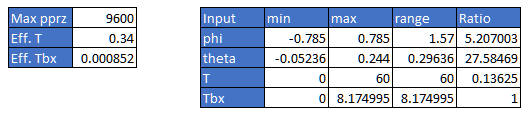

By scaling the weights of the control inputs by the calculated ratios we are normalising the change in inputs wrt their ranges. 

### In_flight_bug has lead to crashes in forward flight

In *autopilot_firmware.c *the "*in_flight" *variable which determines wether the drone is on the ground or flying was defined based on three checks:

- Overall Thrust level less that the defined minimum (ifndef 500 pprz)

- GroundSpeed absolute in Z less than the defined minimum (ifndef 0.2 m/s)

- Acceleration absolute in Z less than the defined minimum (ifndef 20 m/s^2)

The problem with this definition is that VSQP in forward flight does not use the lifting motors and the Thrust being checked does not account for the push prop signal. Therefore, the drone would evaluate to be on the ground and turn off push prop when a constant Z hold was achieved. 

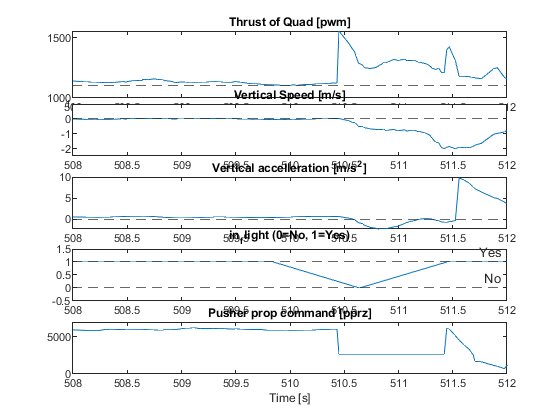

if is_Mac
    p = parselog('/Users/tomasodeponti/Desktop/Flight data of VSQP/log_sd_1404/weird_kill/first/22_04_14__14_20_03.data');
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw'))
else
    p = parselog('C:\Users\Tomaso\Desktop\flight_data_VSQP\log_sd_1404\weird_kill\first\22_04_14__14_20_03.data');
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end 
  
data = p.aircrafts.data.EFF_FULL_INDI;
act = cellfun(@(S) sscanf(S, '%f,').', data.u, 'Uniform', 0);
act = cell2mat(act);
thrust_quad = sum(act(:,1:4),2);

figure(1)
clf
ax1=subplot(4,1,1);
plot(data.timestamp,thrust_quad/4)
hold on
yline(1100,'--')
%yline(1147)
title("Thrust of Quad [pwm]")
ax2=subplot(5,1,2);
plot(data.timestamp,data.speed_D)
hold on
yline(0,'--')
title("Vertical Speed [m/s]")
ylim([-2.5 1]);
ax3=subplot(5,1,3);
plot(data.timestamp,data.body_accel_z+9.81)
hold on
yline(0,'--')
title("Vertical accelleration [m/s^2]")
ax4=subplot(5,1,4);
plot(p.aircrafts.data.ROTORCRAFT_STATUS.timestamp,p.aircrafts.data.ROTORCRAFT_STATUS.ap_in_flight)
ylim([-0.5 1.5]);
hold on
yline([0 1],'--',{'No','Yes'})
title("in_flight (0=No, 1=Yes)")
ax5=subplot(5,1,5);
plot(data.timestamp,data.actuator_thrust_bx_pprz)
title("Pusher prop command [pprz]")
ylim([0,7000])
linkaxes([ax1,ax2,ax3,ax4,ax5],'x');
xlim([508 512]);
xlabel("Time [s]")
hold off

To solve this problem the Thrust check has been changed to account for the push prop command for airframes which have a push prop.

### Hover Flight

The main problem of hover flight has revealed to be position tracking at airspeed of 5-8 m/s. In this region thc drone appear quite unstable and unable to consistently maintain the same position in the airflow

if is_Mac
    p = parselog('/Users/tomasodeponti/Desktop/Flight data of VSQP/log_sd_1204/bad_theta_tracking/22_04_12__17_15_51.data');
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw'))
else
    p = parselog('C:\Users\Tomaso\Desktop\flight_data_VSQP\log_sd_1204\bad_theta_tracking\22_04_12__17_15_51.data');
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end 
  
data = p.aircrafts.data.EFF_FULL_INDI;
act = cellfun(@(S) sscanf(S, '%f,').', data.u, 'Uniform', 0);
act = cell2mat(act);
thrust_quad = sum(act(:,1:4),2);
sf = get_sf(data.timestamp);
f_filter = 10;
order = 4;

figure(8)
clf
ax1=subplot(4,1,1);
plot(data.timestamp,low_butter(act(:,1),f_filter,sf,0,order))
hold on
plot(data.timestamp,low_butter(act(:,2),f_filter,sf,0,order))
plot(data.timestamp,low_butter(act(:,3),f_filter,sf,0,order))
plot(data.timestamp,low_butter(act(:,4),f_filter,sf,0,order))
yline([1100,2000],'--',{'min','max'})
%yline([1300,1400,1500,1600,1700],'--')
ylim([1000,2100]);
legend('front','right','back','left','location','southeast')
grid on
grid minor
title("Thrust of Quad [pwm]")

ax2=subplot(5,1,2);
plot(data.timestamp,low_butter(data.theta_alt,f_filter,sf,0,order))
hold on
plot(data.timestamp,low_butter(data.theta_ref_alt,f_filter,sf,0,order))
yline([-3,13],'--',{'min','max'})
%yline([12,10,8,6],'--')
title("Theta [deg]")
legend('Actual','Reference')
ylim([-9 16]);

ax3=subplot(5,1,3);
plot(data.timestamp,data.position_D)
yline(-3,'--',{'target'})
%hold on 
%plot(data.timestamp,data.position_D_ref)
ylim([-4 -2]);

hold on
title("Position D [m]")

ax4=subplot(5,1,4);
plot(data.timestamp,low_butter(data.phi_alt,f_filter,sf,0,order))
hold on
plot(data.timestamp,low_butter(data.phi_ref_alt,f_filter,sf,0,order))
ylim([-20 20])
yline(0,'--')
legend('Actual','Reference')
title("Phi [deg]")

ax5=subplot(5,1,5);
plot(data.timestamp,low_butter(data.airspeed,f_filter,sf,0,order))
title("Airspeed [m/s]")
ylim([4,10]);
yline(7,'--','windtunnel')
linkaxes([ax1,ax2,ax3,ax4,ax5],'x');
xlim([540 550]);
xlabel("Time [s]")
hold off

The data shows that the drone suffers from strong pitch up disturbances which push motors front and back to saturate completly. Despite the saturation of these motors, the reference pitch angle signal is not tracked well and the actual pitch angle deviates noticeably. 

This pitch up moment can be linked to two main causes. First, due to the fact that the front wing is swept by considerably more airflow than the backwing (blockage from the central body of the drone), a pitch moment imbalance is being induced at slightly positive angles of attack. On the other hand, at slightly negative angles of attack, both half wings can be **assumed** to be swept by equal flow, restauring pitch moment balance. 

Moreover, due to the downwash generated by the back motor, the horizontal tail sees a negative induced angle of attack (see image) even at zero pitch angle.

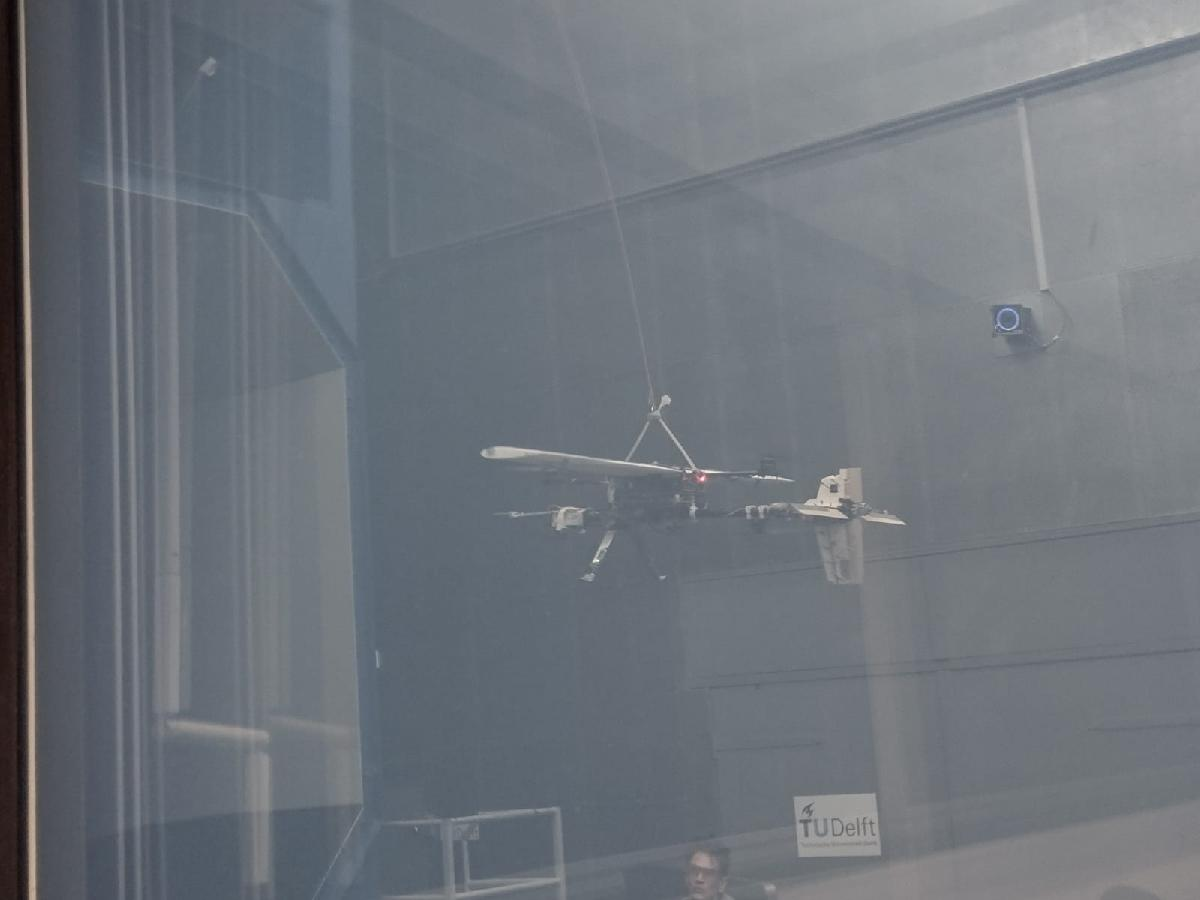 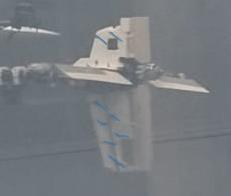

This phenomena is particularly evident in the infamous airspeed region between 5-8 m/s. Beyond the 8 m/s limit the larger $u_\infty$ decreases in magnitude the negative angle of attack. Furthermore, beyond 8 m/s the controller will start to use more aggressively the wing for lift generation, positive angle of attacks will then be commanded, reducing the strenght of the pitch up moment from the horizontal tail. This pitch moment induced by the horizontal tail is further confirmed by the persistent overuse of motor back also in low speed forward flight. 

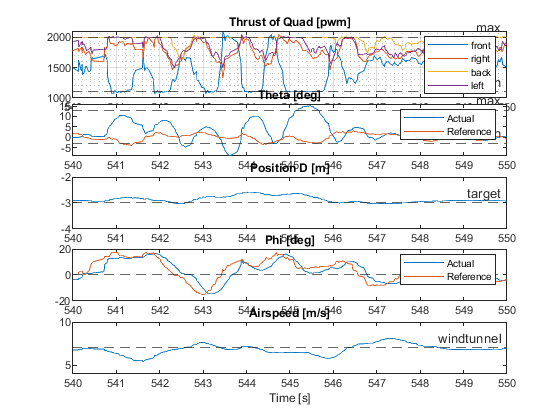

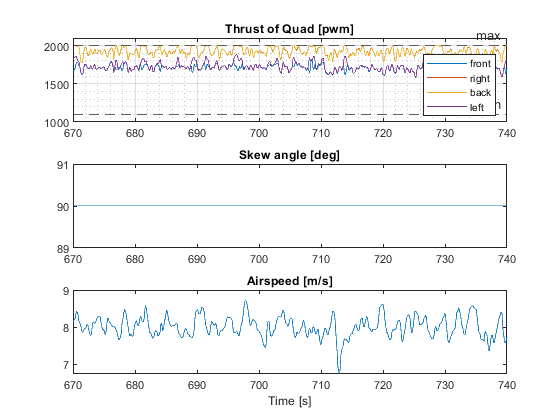

if is_Mac

    p = parselog('/Users/tomasodeponti/Desktop/Flight data of VSQP/log_sd_1304/fwd_pitchgood_motorsoff/ground/22_04_13__18_46_29.data');
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw'))
else
    p = parselog('C:\Users\Tomaso\Desktop\flight_data_VSQP\log_sd_1304\fwd_pitchgood_motorsoff\ground\22_04_13__18_46_29.data');
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end 
  
data = p.aircrafts.data.EFF_FULL_INDI;
act = cellfun(@(S) sscanf(S, '%f,').', data.u, 'Uniform', 0);
act = cell2mat(act);
thrust_quad = sum(act(:,1:4),2);
sf = get_sf(data.timestamp);
f_filter = 2;
order = 4;

figure(7)
clf
ax1=subplot(3,1,1);
plot(data.timestamp,low_butter(act(:,1),f_filter,sf,0,order))
hold on
plot(data.timestamp,low_butter(act(:,2),f_filter,sf,0,order))
plot(data.timestamp,low_butter(act(:,3),f_filter,sf,0,order))
plot(data.timestamp,low_butter(act(:,4),f_filter,sf,0,order))
yline([1100,2000],'--',{'min','max'})
%yline([1300,1400,1500,1600,1700],'--')
ylim([1000,2100]);
legend('front','right','back','left','location','southeast')
grid on
grid minor
title("Thrust of Quad [pwm]")


ax2=subplot(3,1,2);
plot(data.timestamp,data.wing_angle_deg_sp)

%hold on 
%plot(data.timestamp,data.position_D_ref)
%ylim([ -2]);
hold on
title("Skew angle [deg]")


ax3=subplot(3,1,3);
plot(data.timestamp,low_butter(data.airspeed,f_filter,sf,0,order))
title("Airspeed [m/s]")
%ylim([10,14.5]);
linkaxes([ax1,ax2,ax3],'x');
xlim([670 740]);
xlabel("Time [s]")
hold off

Two main solution were adopted in order to contain the pitch moment disturbances. 

First of all, in the airspeed region of interest when in quad mode, a preferred state $\theta_{pref}=-2^\circ$ is commanded. This limits the pitch up moment generated by the front half wing as already described. 

Secondly, the control objective weights of the stabilization WLS have been change in favour of the prioritization of pitch control. From a preliminary CAD model of the drone, it can be noticed that ...

...the roll moment of inertia is consistly about one order of magnitude lower than the pitch moment of inertia across the range of possible skew angles. This is of course also reflected by the effectivness matrix of the innerloop which has roll effectiveness values one order of magnitude higher than the pitch ones. 

In a nutshell we can deduce that it takes much less effort from the side motors to track a roll reference signal compared to the longitudadinal motors when asked to follow a pitch reference signal. Furthermore, it can be noticed from the previous plot that the reference signal of roll is being followed quite closely. Therefore, it can be deduced that there is some room to prioritize and directly more control energy towards pitch control while minimally affect roll control. 

The WLS weights of the control objective of the inner loop are then changed from:

to:

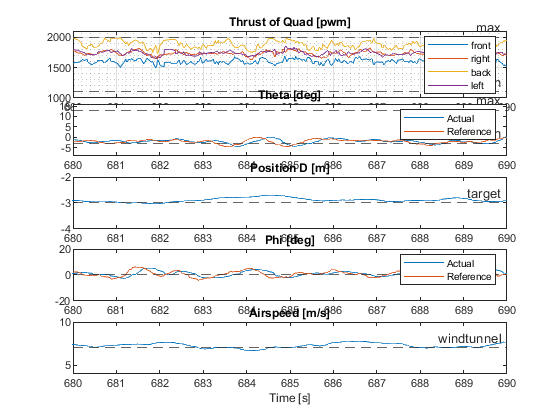

if is_Mac
    p = parselog('/Users/tomasodeponti/Desktop/Flight data of VSQP/log_sd_1304/first_flight_better_theta_control/ground/22_04_13__11_58_14.data');
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw'))
else
    p = parselog('C:\Users\Tomaso\Desktop\flight_data_VSQP\log_sd_1304\first_flight_better_theta_control\ground\22_04_13__11_58_14.data');
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end 
  
data = p.aircrafts.data.EFF_FULL_INDI;
act = cellfun(@(S) sscanf(S, '%f,').', data.u, 'Uniform', 0);
act = cell2mat(act);
thrust_quad = sum(act(:,1:4),2);
sf = get_sf(data.timestamp);
f_filter = 10;
order = 4;

figure(8)
clf
ax1=subplot(4,1,1);
plot(data.timestamp,low_butter(act(:,1),f_filter,sf,0,order))
hold on
plot(data.timestamp,low_butter(act(:,2),f_filter,sf,0,order))
plot(data.timestamp,low_butter(act(:,3),f_filter,sf,0,order))
plot(data.timestamp,low_butter(act(:,4),f_filter,sf,0,order))
yline([1100,2000],'--',{'min','max'})
%yline([1300,1400,1500,1600,1700],'--')
ylim([1000,2100]);
legend('front','right','back','left','location','southeast')
grid on
grid minor
title("Thrust of Quad [pwm]")

ax2=subplot(5,1,2);
plot(data.timestamp,low_butter(data.theta_alt,f_filter,sf,0,order))
hold on
plot(data.timestamp,low_butter(data.theta_ref_alt,f_filter,sf,0,order))
yline([-3,13],'--',{'min','max'})
%yline([12,10,8,6],'--')
title("Theta [deg]")
legend('Actual','Reference')
ylim([-9 16]);

ax3=subplot(5,1,3);
plot(data.timestamp,data.position_D)
yline(-3,'--',{'target'})
%hold on 
%plot(data.timestamp,data.position_D_ref)
ylim([-4 -2]);

hold on
title("Position D [m]")

ax4=subplot(5,1,4);
plot(data.timestamp,low_butter(data.phi_alt,f_filter,sf,0,order))
hold on
plot(data.timestamp,low_butter(data.phi_ref_alt,f_filter,sf,0,order))
ylim([-20 20])
yline(0,'--')
legend('Actual','Reference')
title("Phi [deg]")

ax5=subplot(5,1,5);
plot(data.timestamp,low_butter(data.airspeed,f_filter,sf,0,order))
title("Airspeed [m/s]")
ylim([4,10]);
yline(7,'--','windtunnel')
linkaxes([ax1,ax2,ax3,ax4,ax5],'x');
xlim([680 690]);
xlabel("Time [s]")
hold off

As the plot above show, with the implemented solutions a much closer to the reference and more contained pitch profile is achieved. Saturation does not occur on neither the front nor the back motors. There is no observable negative effect on roll reference tracking. 

### Forward Flight

A quick recap of the outerloop WLS cost function is:


$$C\left(u\right)=\gamma \;||\;W_v \left(G\;u-v\right)||+||W_u \left(u-u_{\textrm{pref}} \right)||$$


Now, the effectiveness of changing theta to control the Z axis can be augmented by a term representing the contribution to lift of the wing. First we **assume** that the lift vector is only tilted by the roll angle. Furthermore, we **assume** that $\frac{\textrm{dL}}{d\theta }\;\frac{1}{m}=\textrm{LIFTD}$for a constant geomtry wing, is only a function pitch angle, aispeed and Skew angle. Therefore:


$$G_{32} =-\cos \left(\phi \right)\sin \left(\theta \right)T+\cos \left(\phi \right)\textrm{LIFTD}\left(\theta ,\textrm{as},\Lambda \right)$$


As a starting point for simplicity, let's **assume** $\Lambda ={90}^{\circ }$(FWD mode). Simple lifting theory states that :

$L\left(\theta ,\mathrm{as}\right)=\frac{1}{2}\rho \;C_L \;S\;{\left(\mathrm{as}\right)}^2$ therefore the change in $a_z$ due to a change in theta can be calculated as :

$\mathrm{LIFTD}\left(\theta ,\mathrm{as}\right)=\frac{1}{2}\rho {S\left(\mathrm{as}\right)}^2 \frac{1}{m}\frac{{\mathrm{dC}}_L }{d\theta }$ Now, air density and wing area can be **assumed** constant and are known variables. Airspeed as well can be detected by the pitot tube. The only left unknow is $\frac{{\textrm{dC}}_L }{d\theta }$ which can be estimated by performing an analysis in xflr5 of the wing. (look better into the assumptions of xflr5)

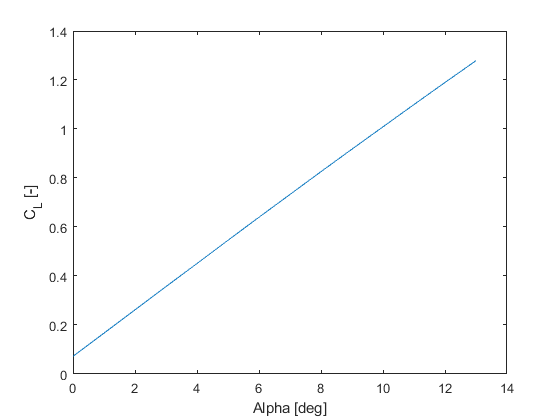

angles = [0,1,2,3,4,5,6,7,8,9,10,11,12,13];
cl = [0.0723,0.167,0.262,0.357,0.451,0.546,0.640,0.733,0.826,0.918,1.009,1.100,1.190,1.279];
figure(4)
clf
plot(angles,cl)
xlabel("Alpha [deg]")
ylabel("C_L [-]")

Now we can **assume **that the flight path is small and negligible, therefore $\alpha = \theta$. We can linerize the C_L curve by calculating the slope at two arbitrary points (e.g. smallest and biggest angle value). This leads to the lift pitch effectiveness value of  $\frac{{\textrm{dC}}_L }{d\theta }$=0.0928. With this value in mind it is also possible to calculate around which speed we expect the wing to generate enough lift. 


$$\textrm{as}=\sqrt{\frac{m\;g}{0\ldotp 5\;\rho \;S\;C_{\textrm{Lmax}} }}=\sqrt{\frac{3\ldotp 5\;*9\ldotp 81}{0\ldotp 5*1\ldotp 225*1\ldotp 56*0\ldotp 235}}=12\ldotp 37\;\left\lbrack \frac{m}{s}\right\rbrack$$


One must now realise that in order to achieve a desired $\Delta_{az}$ there is not a single solution but actually thera a number of feasible solutions. Z accleration can indeed be achieved by changing $\theta$, T or even the rpm of the push motor.

On the other hand, only one of the feasible solutions will yeild minum cost according to the linear function $C(u)$. Therefore, one by selecting weights in $W_u$ can direct WLS towards the evaluation of a preferred solution. 

In general having a higher $W_u$ weight for Thrust than for pitch will steer the WLS routine to prefer a solution more biased towards $\theta$. Furthermore, the preferred change for the inputs further influences the optimal solutions. $\Delta_{T_{pref}}$ is set to the minimum possible, which is the change that brings T to zero. On the other hand $\Delta_{\theta_{pref}}$ is set to 0 because pitch is a virtual actuator which at higher airspeeds does not have a high power cost. As a consequence pitch is encouraged to follow the output of the primary function and not deviate from it much. 

The following test data was recorded running input weights as described:


$$W_u =\left\lbrack \begin{array}{cccc}
10 & 0 & 0 & 0\\
0 & 27 & 0 & 0\\
0 & 0 & 5 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


These weights indicate a propensity to use the Thrust over pitch angle.( Also this flight run was done with  $\Delta_{\theta_{pref}}$ set to delta minimum). The plot indeed shows that even if we reach a velocity which would teoretically, and we will show also experimentally later, be enough for the wing to generate all the necessary Lift (14 m/s), The average thrust command is still 1400[pwm] while theta is not maximised 4 [deg]. 

This indicates a propensity towards using thrust over theta. Another interesting aspect is that the thrust curve can be observed to constantly decline with higher airspeed. On the other hand, $\theta$ first is commanded to increase to around 10[deg] and then as airspeed increases a lower value is commanded, indicating the awarness by the controller of the increasing effectiveness of the wing. 

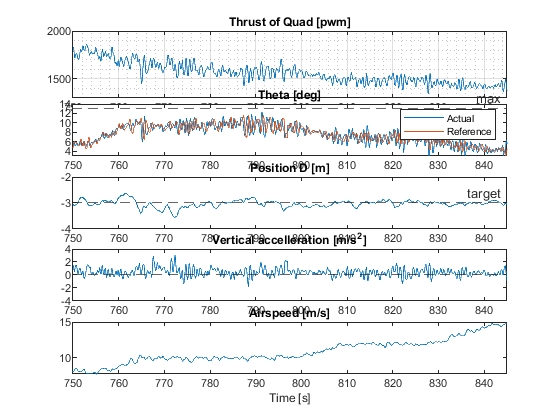

if is_Mac
    p = parselog('/Users/tomasodeponti/Desktop/Flight data of VSQP/log_sd_1304/fwd_pitchgood_motorsoff/ground/22_04_13__18_46_29.data');
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw'))
else
    p = parselog('C:\Users\Tomaso\Desktop\flight_data_VSQP\log_sd_1304\fwd_pitchgood_motorsoff\ground\22_04_13__18_46_29.data');
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end 
  
data = p.aircrafts.data.EFF_FULL_INDI;
act = cellfun(@(S) sscanf(S, '%f,').', data.u, 'Uniform', 0);
act = cell2mat(act);
thrust_quad = sum(act(:,1:4),2);
sf = get_sf(data.timestamp);
f_filter = 2;
order = 4;

figure(5)
clf
ax1=subplot(4,1,1);
plot(data.timestamp,low_butter(thrust_quad/4,f_filter,sf,0,order))
hold on
yline(1100,'--')
%yline([1300,1400,1500,1600,1700],'--')
ylim([1300,2000]);
grid on
grid minor
title("Thrust of Quad [pwm]")

ax2=subplot(5,1,2);
plot(data.timestamp,low_butter(data.theta_alt,f_filter,sf,0,order))
hold on
plot(data.timestamp,low_butter(data.theta_ref_alt,f_filter,sf,0,order))
yline([-3,13],'--',{'min','max'})
%yline([12,10,8,6],'--')
title("Theta [deg]")
legend('Actual','Reference')
ylim([3 14]);

ax3=subplot(5,1,3);
plot(data.timestamp,data.position_D)
yline(-3,'--',{'target'})
%hold on 
%plot(data.timestamp,data.position_D_ref)
ylim([-4 -2]);

hold on
title("Position D [m]")

ax4=subplot(5,1,4);
plot(data.timestamp,low_butter(data.body_accel_z+9.81,f_filter,sf,0,order))
ylim([-4 4])
yline(0,'--')
title("Vertical accelleration [m/s^2]")

ax5=subplot(5,1,5);
plot(data.timestamp,low_butter(data.airspeed,f_filter,sf,0,order))
title("Airspeed [m/s]")
%ylim([10,14.5]);
linkaxes([ax1,ax2,ax3,ax4,ax5],'x');
xlim([750 845]);
xlabel("Time [s]")
hold off

Reversing the weight distribution would instead encourage the use of theta over thrust. This is a more desirable beaviour as we would like a grradual shift of upward force generation from the motors to the wing.


$$W_u =\left\lbrack \begin{array}{cccc}
10 & 0 & 0 & 0\\
0 & 18 & 0 & 0\\
0 & 0 & 32 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


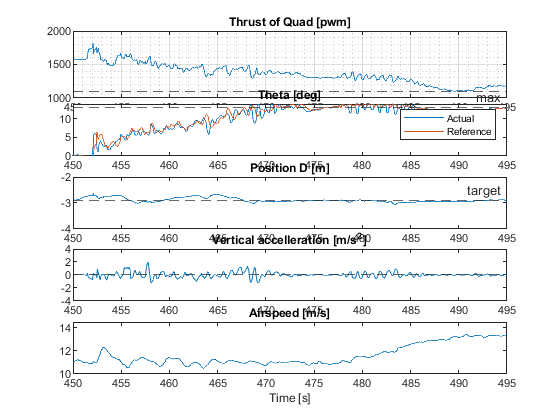

if is_Mac
    p = parselog('/Users/tomasodeponti/Desktop/Flight data of VSQP/log_sd_1404/weird_kill/first/22_04_14__14_20_03.data');
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw'))
else
    p = parselog('C:\Users\Tomaso\Desktop\flight_data_VSQP\log_sd_1404\weird_kill\first\22_04_14__14_20_03.data');
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end 
  
data = p.aircrafts.data.EFF_FULL_INDI;
act = cellfun(@(S) sscanf(S, '%f,').', data.u, 'Uniform', 0);
act = cell2mat(act);
thrust_quad = sum(act(:,1:4),2);
sf = get_sf(data.timestamp);
f_filter = 5;
order = 4;

figure(3)
clf
ax1=subplot(4,1,1);
plot(data.timestamp,low_butter(thrust_quad/4,f_filter,sf,0,order))
hold on
yline(1100,'--')
%yline([1300,1400,1500,1600,1700],'--')
ylim([1000,2000]);
grid on
grid minor
title("Thrust of Quad [pwm]")

ax2=subplot(5,1,2);
plot(data.timestamp,low_butter(data.theta_alt,f_filter,sf,0,order))
hold on
plot(data.timestamp,low_butter(data.theta_ref_alt,f_filter,sf,0,order))
yline([-3,13],'--',{'min','max'})
%yline([12,10,8,6],'--')
title("Theta [deg]")
legend('Actual','Reference')
ylim([0 14]);

ax3=subplot(5,1,3);
plot(data.timestamp,data.position_D)
yline(-2.9,'--',{'target'})
%hold on 
%plot(data.timestamp,data.position_D_ref)
ylim([-4 -2]);

hold on
title("Position D [m]")

ax4=subplot(5,1,4);
%plot(data.timestamp,low_butter(data.body_accel_z+9.81,f_filter,sf,0,order))
plot(p.aircrafts.data.GUIDANCE_INDI_HYBRID.timestamp,p.aircrafts.data.GUIDANCE_INDI_HYBRID.accelned_filt_z)
ylim([-4 4])
yline(0,'--')
title("Vertical accelleration [m/s^2]")

ax5=subplot(5,1,5);
plot(data.timestamp,low_butter(data.airspeed,f_filter,sf,0,order))
title("Airspeed [m/s]")
ylim([10,14.5]);
linkaxes([ax1,ax2,ax3,ax4,ax5],'x');
xlim([450 495]);
xlabel("Time [s]")
hold off

From an analysis of the graph a few key conclusions can be derived. 

The drone is being set to NAV in from ATT in a detected airflow of 11 m/s. The WLS routing slowly converges to the solution that at this airspeed optimal Z control is achieved with maximum theta (14 deg) and an average thrust level from the quad motors of 1300 [pwm]. We can indeed observe how the thrust curve falls as more theta is being used While maintaining good position tracking in the Z axis.

As airspeed is being increased further towards 14 m/s, WLS calculates that the new optimal state is to further decrease the thrust level as the wing can generate more lift. At 490[s] it can be observed that idle state is reached. On the other hand, a slight acceleration downwards is registered indicating that at this airspeed the drone cannot yet only rely on the wing for lift generation. Therefore, shortly after thrust level is slightly increased. 

In conclusion, we can understand that the fully FWD airspeed is slightly higher than 13 m/s. Now taking into account that a 1-2 m/s offset was observed in the reading of the pitot tube, it can be concluded that this finding is inline with the model of the wing. Indeed at a speed of 11 m/s the wing is on the verge of being able to generate all the required lift .

***One future interesting test would be increase the airspeed beyond the 14 m/s mark which triggered the kill bug and verify that as expected lower and lower pitch angles are commanded with fully idle motors. ***

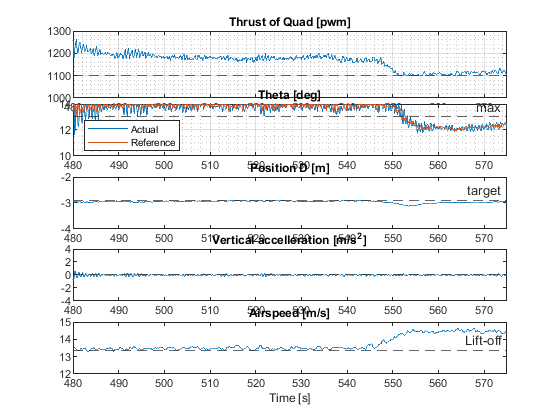

if is_Mac
    p = parselog('/Users/tomasodeponti/Desktop/Flight data of VSQP/log_sd_1404/weird_kill/second/22_04_14__14_42_48.data');
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw'))
else
    p = parselog('C:\Users\Tomaso\Desktop\flight_data_VSQP\log_sd_1404\weird_kill\second\22_04_14__14_42_48.data');
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end 
  
data = p.aircrafts.data.EFF_FULL_INDI;
act = cellfun(@(S) sscanf(S, '%f,').', data.u, 'Uniform', 0);
act = cell2mat(act);
thrust_quad = sum(act(:,1:4),2);
sf = get_sf(data.timestamp);
f_filter = 5;
order = 4;

figure(6)
clf
ax1=subplot(4,1,1);
plot(data.timestamp,low_butter(thrust_quad/4,f_filter,sf,0,order))
hold on
yline(1100,'--')
%yline([1300,1400,1500,1600,1700],'--')
ylim([1000,1300]);
grid on
grid minor
title("Thrust of Quad [pwm]")

ax2=subplot(5,1,2);
plot(data.timestamp,low_butter(data.theta_alt,f_filter,sf,0,order))
hold on
plot(data.timestamp,low_butter(data.theta_ref_alt,f_filter,sf,0,order))
yline([-3,13],'--',{'min','max'})
%yline([12,10,8,6],'--')
grid on
grid minor
title("Theta [deg]")
legend('Actual','Reference','Location','southwest')
ylim([10 14]);

ax3=subplot(5,1,3);
plot(data.timestamp,data.position_D)
yline(-2.9,'--',{'target'})
%hold on 
%plot(data.timestamp,data.position_D_ref)
ylim([-4 -2]);

hold on
title("Position D [m]")

ax4=subplot(5,1,4);
plot(p.aircrafts.data.GUIDANCE_INDI_HYBRID.timestamp,p.aircrafts.data.GUIDANCE_INDI_HYBRID.accelned_filt_z)
ylim([-4 4])
yline(0,'--')
title("Vertical accelleration [m/s^2]")

ax5=subplot(5,1,5);
plot(data.timestamp,low_butter(data.airspeed,f_filter,sf,0,order))
title("Airspeed [m/s]")
ylim([12,15]);
yline(13.37,'--','Lift-off')
linkaxes([ax1,ax2,ax3,ax4,ax5],'x');
xlim([480 575]);
xlabel("Time [s]")
hold off

### Transition

Thruth be told is that lift is not only a function of $\theta$ and airspeed but actually also of $\Lambda$. Now, developing a detailed model at high skew angles of the generated lift can be particularly complex. For example, past $45^\circ$ of skew, the majority of the airspeed component will be spanwise. It would be complex to predict wether also this spanwise component can generate lift with the wing resulting to be a lifting body also if wet from the side. Furthermore, at high skew angles one wing is much more swept by the airflow than the other due to the blockage effect of the central body. Therefore, we take a simplified approach by **assuming** that the lift generated is a function of the perpendicular component of airspeed to the chord and that INDI can flush out other model discrepancies. 

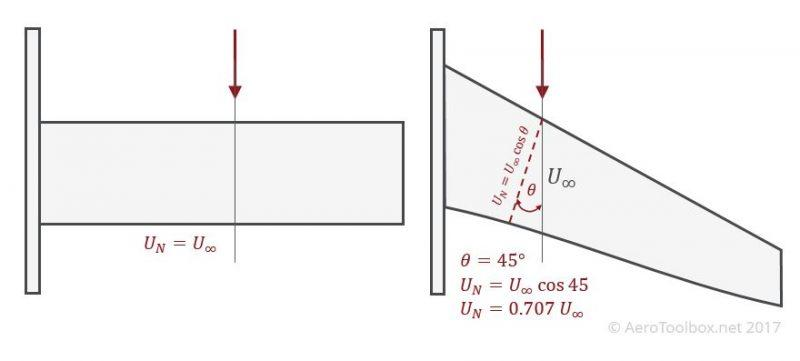

With these considerations in mind we can develop a new definition of lift accounting for the skew angle. In Paparazzi the skew angle is defined to be 0 at QUAD to facilitate the implementation fo the roptational controller. This means that we have to use $sin(\Lambda)$instead of $cos(\Lambda)$:


$$L\left(\theta ,\mathrm{as},\Lambda \right)=\frac{1}{2}\rho \;C_L \;S\;{\left(\mathrm{as}*\sin \left(\Lambda \right)\right)}^2 =\frac{1}{2}\rho \;C_L \;S\;{\left(\mathrm{as}\right)}^{2\;} \sin^2 \left(\Lambda \right)$$


It then also follows that :


$$\mathrm{LIFTD}\left(\theta ,\mathrm{as},\Lambda \right)=\frac{1}{2}\rho {S\sin^2 \left(\Lambda \right)\left(\mathrm{as}\right)}^2 \frac{1}{m}\frac{{\mathrm{dC}}_L }{d\theta }$$


Now, again because modelling of the generated lift is uncertain at high (low in the paparazzi convention) skew angles and at low airspeeds we force LIFTD to be 0 under 5 m/s and under $30^\circ$ skew angle. More precisely, the manipulation with regards to skew follows :


$$\mathrm{LIFTD}\left(\theta ,\mathrm{as},\Lambda \right)={\mathrm{LIFTD}}_{\min } +\sin^2 \left(\mathrm{bound}\left(\left(\Lambda -{30}^{\circ } \right)*1\ldotp 5,0^{\circ } ,{90}^{\circ } \right)\right)*\left(0\ldotp 0928-{\mathrm{LIFTD}}_{\min } \right)$$


With ${\mathrm{LIFTD}}_{\min }$ being a tunable parameter that can be set to represent a constrant contribution of the wing to lift at very high skew angles (low for Paparazzi). 

As for the scheduling of the effectiveness of motors and aerodynamic surfaces with $\Lambda$ for stabilization, recall the definition of the control moment:


$$M_{c\;} =\left\lbrack \begin{array}{c}
{\mathrm{bk}}_1 \left(\omega_1^2 \;-\sin \left(\Lambda \right)\omega_2^2 {\;-\omega }_3^{2\;\;} +\sin \left(\Lambda \right)\omega_4^2 \right)+{\cos \left(\Lambda \right)l}_a {\;k}_a \left(\delta_{a_r } -\delta_{a_l } \right)v^2 \\
{\mathrm{bk}}_1 \left(-\cos \left(\Lambda \right)\omega_2^2 +\cos \left(\Lambda \right)\omega_4^2 \right)+l_e {\;k}_e {\;\delta }_e +{\sin \left(\Lambda \right)l}_a {\;k}_a \left(\delta_{a_r } -\delta_{a_l } \right)v^2 \\
k_2 \left(\omega_1^2 -\omega_2^2 {\;+\omega }_3^{2\;\;} -\omega_4^2 \right)+l_r {\;k}_r {\;\delta }_r v^2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
{\mathrm{bk}}_1  & -\sin \left(\Lambda \right){\mathrm{bk}}_1  & -{\mathrm{bk}}_1  & \sin \left(\Lambda \right){\mathrm{bk}}_1 \\
0 & -\cos \left(\Lambda \right){\mathrm{bk}}_1  & 0 & \cos \left(\Lambda \right){\mathrm{bk}}_1 \\
k_2  & {-k}_2  & k_2  & -k_2 
\end{array}\right\rbrack \omega^{2\;} +\left\lbrack \begin{array}{cccc}
-{\cos \left(\Lambda \right)l}_a {\;k}_{a\;} v^2  & {\cos \left(\Lambda \right)l}_a {\;k}_a \;v^2  & 0 & 0\\
-{\sin \left(\Lambda \right)l}_a {\;k}_a \;v^2  & {\sin \left(\Lambda \right)l}_a {\;k}_a \;v^2  & l_e {\;k}_e \;v^2  & 0\\
0 & 0 & 0 & l_r {\;k}_r \;v^2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\delta_{a_l } \\
\delta_{a_r } \\
\delta_e \\
\delta_r 
\end{array}\right\rbrack$$


This results in a simple trigonometric scheduling of the effectiveness values for the ailerons and the side motors. We further introduce some angle limitations to avoid undesirable control actions especially evident when the effectiveness value of an actuator tends to zero but is not perfectly zero. For example, we set the ailerons to be effective only beyond $45^\circ$ when we can better describe the wing lift generation with simple lifting theory. On the same line, side motors are effective in roll only untill $70^\circ$ beyond which the roll arm tends to zero. Pitch and Yaw control with all motors is always turned on and the gradual exclusion of the motors from stabilisation is left to the WLS discretion. 

Succesful transition has been achieved at 10 m/s and 12 m/s. At 14 m/s the kill bug prevented further testing. Remember that pitot tube has an offset ranging from +1/+2 m/s w.r.t. the windtunnel. 

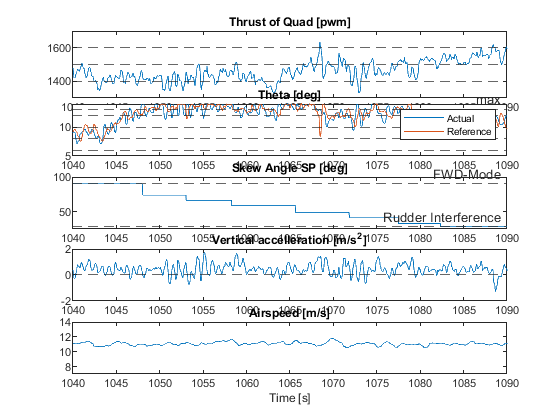

p = parselog('C:\Users\Tomaso\Desktop\flight_data_VSQP\log_sd_1404\transition_10ms_success\ground\22_04_14__13_06_57.data');
addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
data = p.aircrafts.data.EFF_FULL_INDI;
act = cellfun(@(S) sscanf(S, '%f,').', data.u, 'Uniform', 0);
act = cell2mat(act);
thrust_quad = sum(act(:,1:4),2);
sf = get_sf(data.timestamp);
f_filter = 5;
order = 4;

figure(2)
clf
ax1=subplot(4,1,1);
plot(data.timestamp,low_butter(thrust_quad/4,f_filter,sf,0,order))
hold on
yline(1100,'--')
yline([1300,1400,1500,1600,1700],'--')
ylim([1300,1700]);

title("Thrust of Quad [pwm]")
ax2=subplot(5,1,2);
plot(data.timestamp,low_butter(data.theta_alt,f_filter,sf,0,order))
hold on
plot(data.timestamp,low_butter(data.theta_ref_alt,f_filter,sf,0,order))
yline([-3,13],'--',{'min','max'})
yline([12,10,8,6],'--')
title("Theta [deg]")
legend('Actual','Reference')
ylim([5 14]);
ax3=subplot(5,1,3);
plot(data.timestamp,data.wing_angle_deg_sp)
ylim([25 100]);
hold on
yline([0 90],'--',{'Quad-Mode','FWD-Mode'})
yline(28,'--','Rudder Interference')
title("Skew Angle SP [deg]")
ax4=subplot(5,1,4);
plot(data.timestamp,low_butter(data.body_accel_z+9.81,f_filter,sf,0,order))
hold on
yline(0,'--')
title("Vertical accelleration [m/s^2]")
ax5=subplot(5,1,5);
plot(data.timestamp,low_butter(data.airspeed,f_filter,sf,0,order))
title("Airspeed [m/s]")
ylim([7,14]);
linkaxes([ax1,ax2,ax3,ax4,ax5],'x');
xlim([1040 1090]);
xlabel("Time [s]")
hold off

### Reasons for Oscillations

Left to be understood are the reasons for these oscillating references. Is there an oscillation in the reference because thereis noise? or is it the other way around?

possible reasons could be :

- Non linearity of the outerloop matrix leads to oscillation around the minimum

- Virtual actuators are much slower than thrust and push prop

- Not perfectly tuned gains. 

- Asymmetry in moment of inertia distribution but sdymmetrical NE gains. 